clear variables;

## Image file processing

img_rgb = imread('Lenna.png');
disp('Display image')

Display image


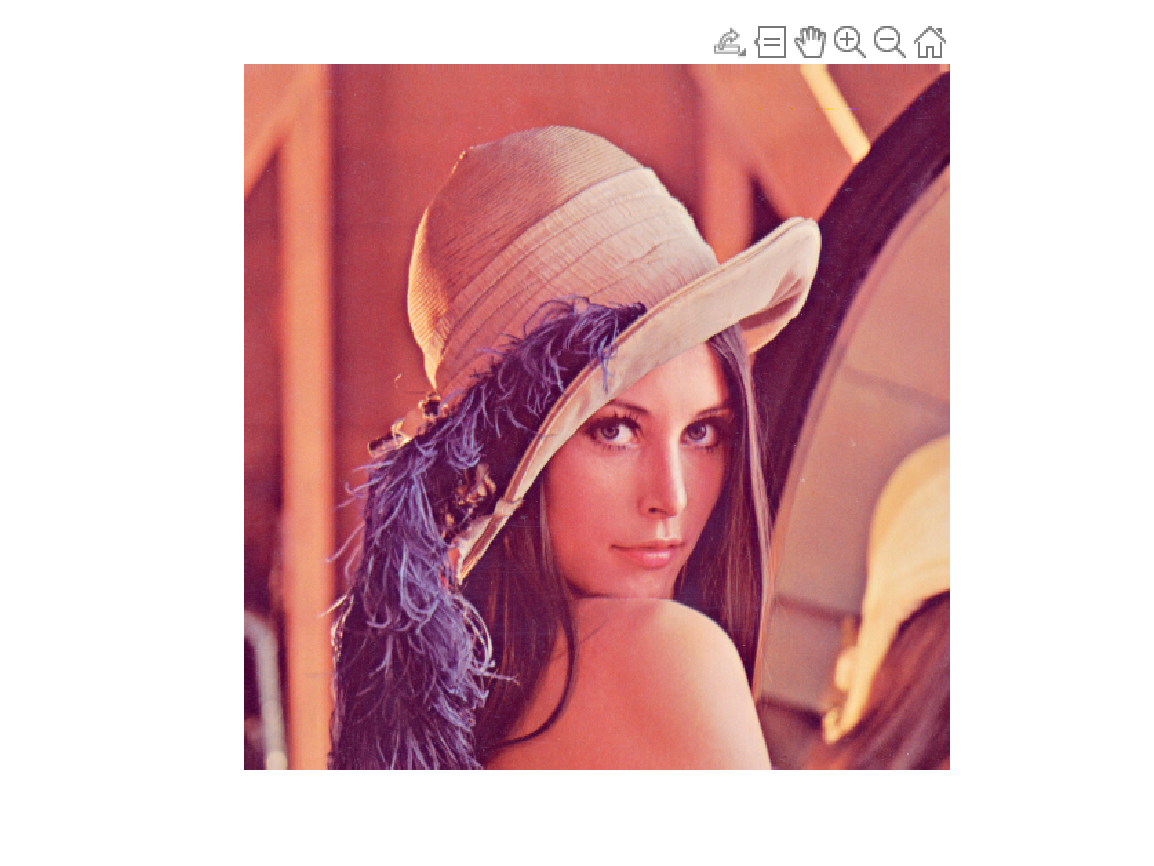

imshow(img_rgb)

## Convert an image to grayscale

img_gray = rgb2gray(img_rgb);
disp('Display grayscale image')

Display grayscale image


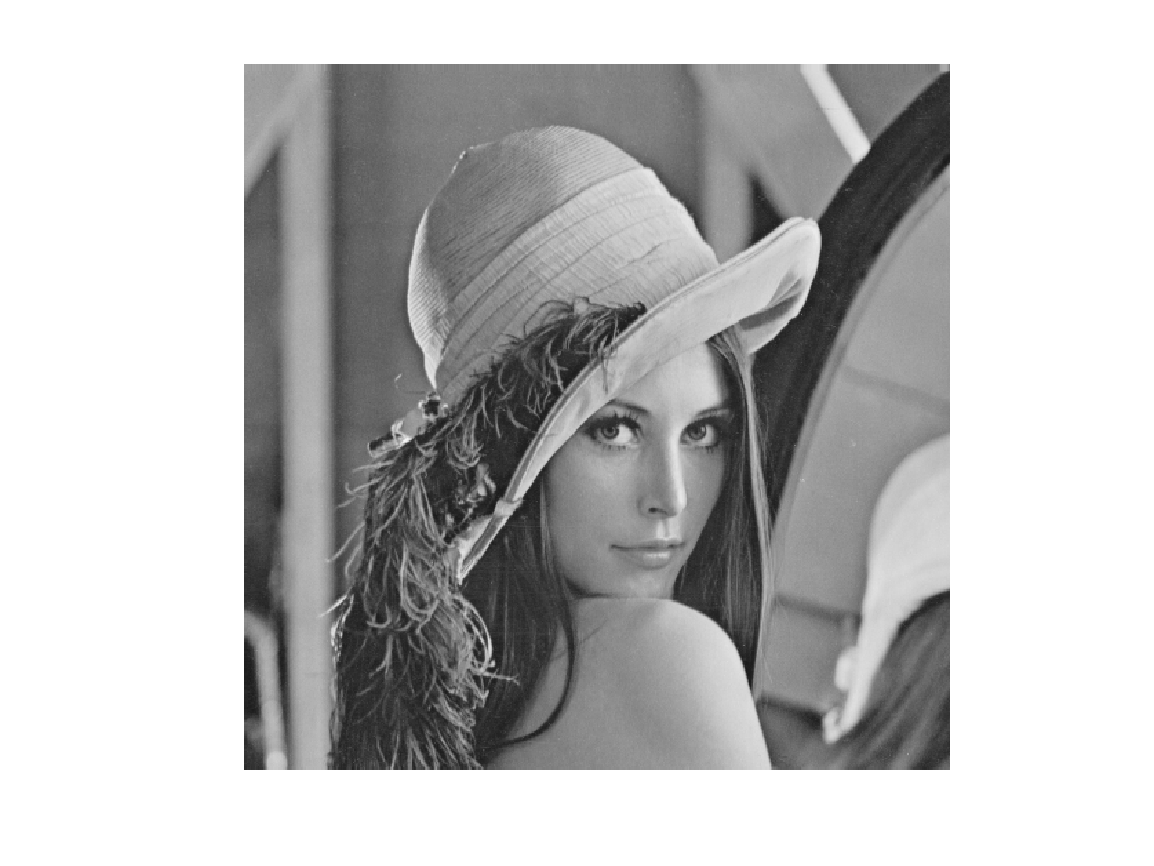

imshow(img_gray)

## Arithmetic operations on grayscale image matrices

disp('Display brighter grayscale image')

Display brighter grayscale image


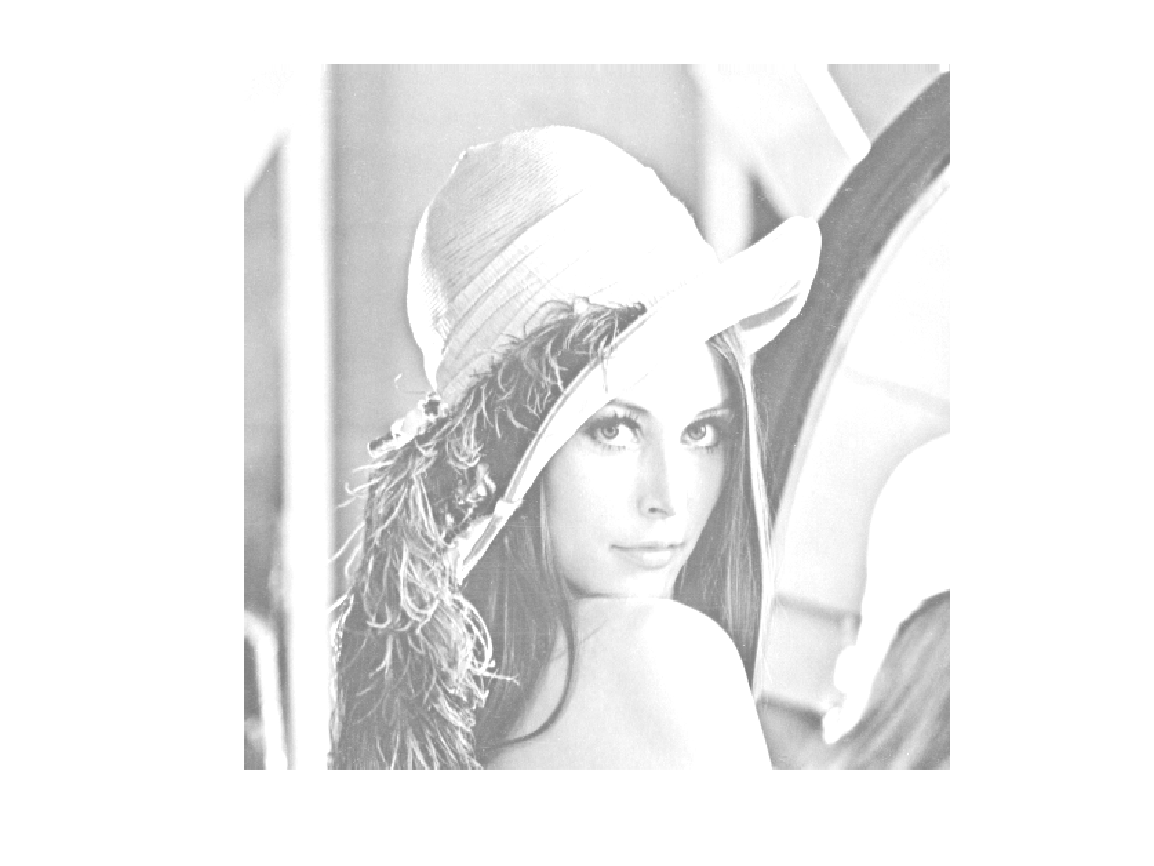

imshow(img_gray+100)

## Separate RGB image channels

r = img_rgb(:, :, 1);
g = img_rgb(:, :, 2);
b = img_rgb(:, :, 3);
disp('Display r-channel grayscale image')

Display r-channel grayscale image


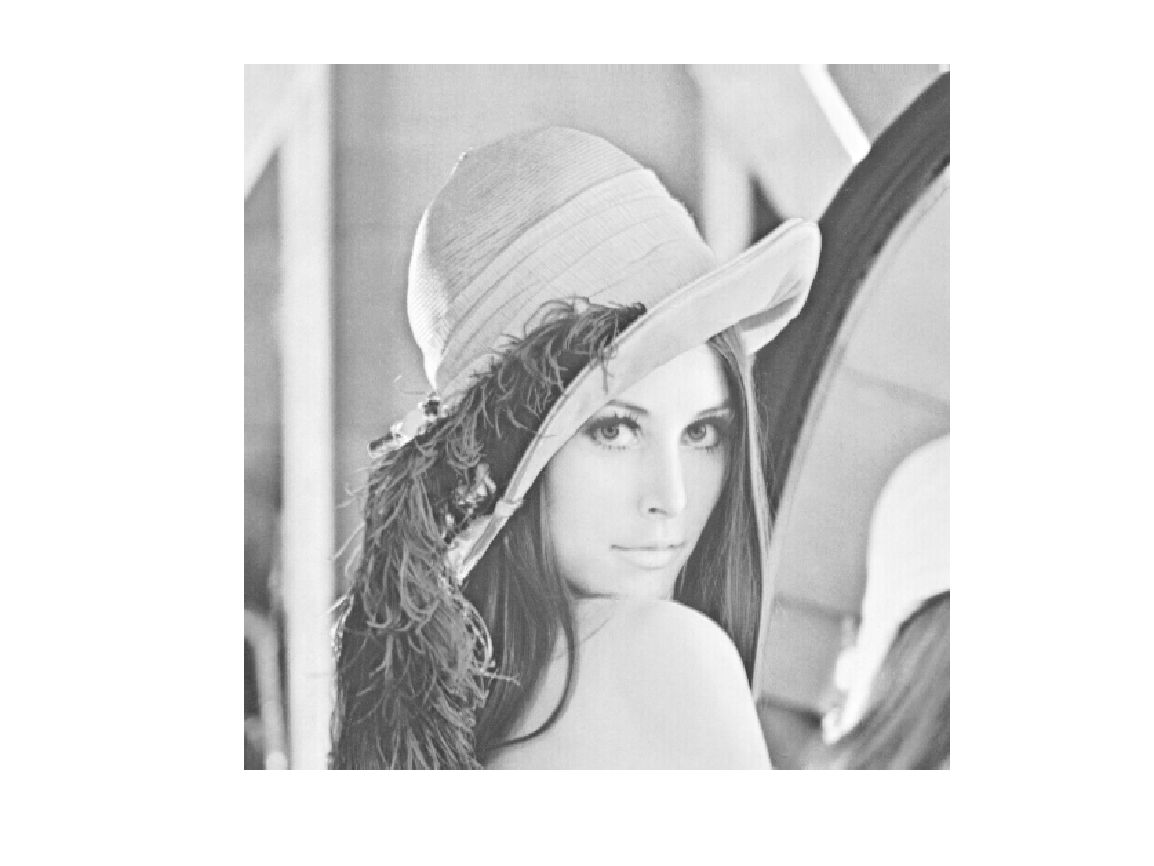

imshow(r)

disp('Display g-channel grayscale image')

Display g-channel grayscale image


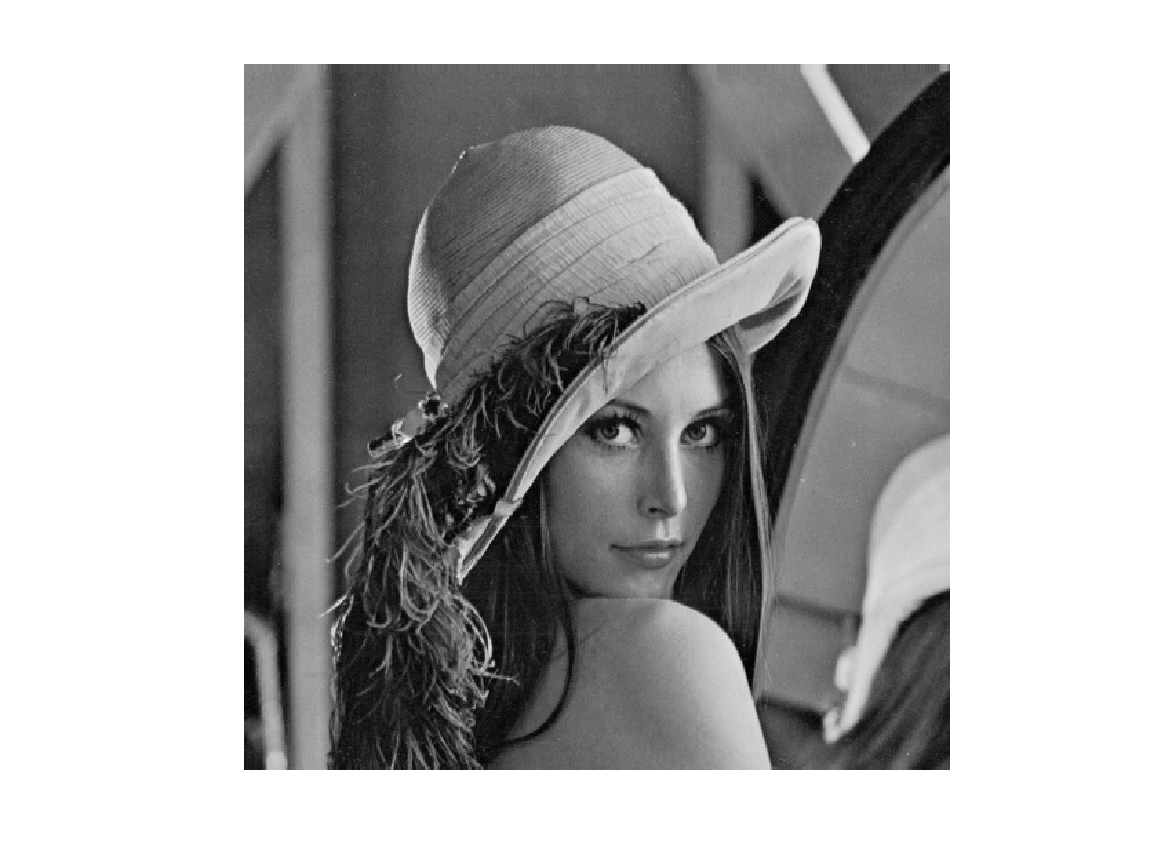

imshow(g)

disp('Display b-channel grayscale image')

Display b-channel grayscale image


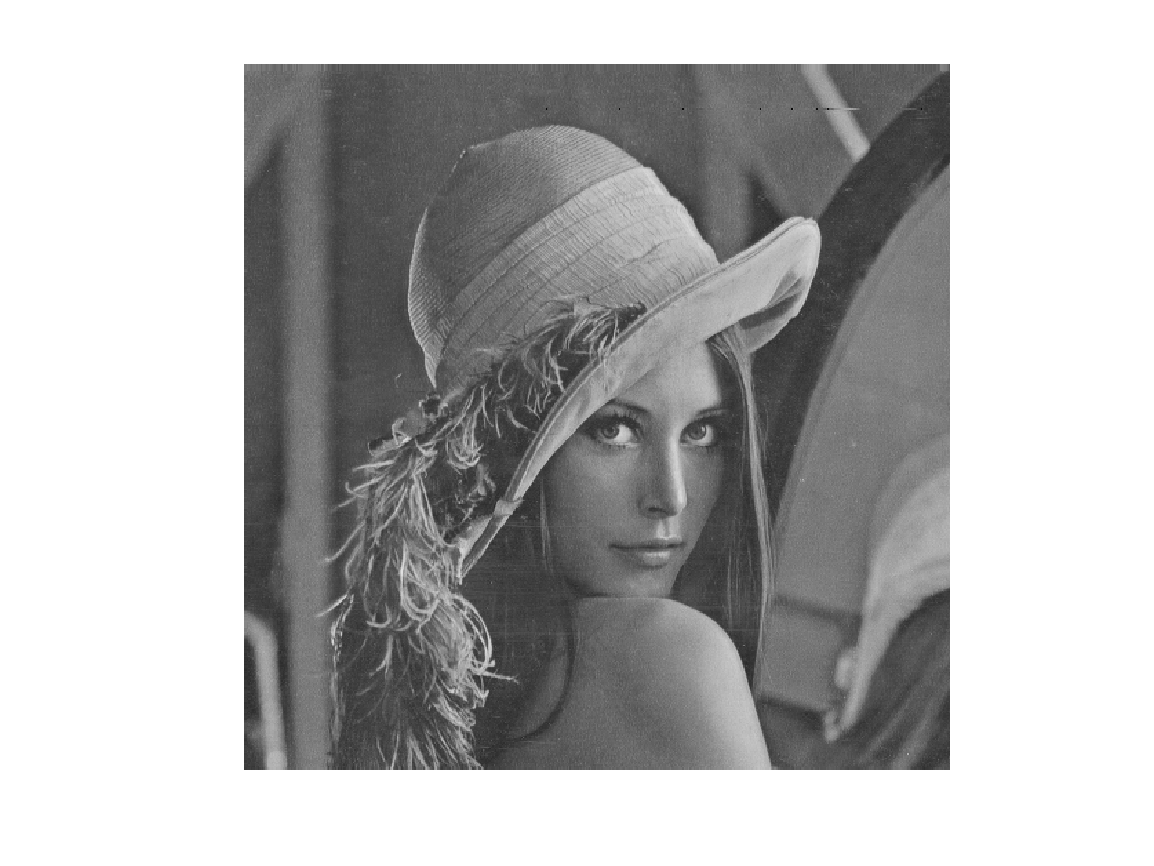

imshow(b)

## Arithmetic operations on RGB image matrices

img_rgb_r = img_rgb;
img_rgb_g = img_rgb;
img_rgb_b = img_rgb;
img_rgb_r(:, :, 1) = img_rgb_r(:, :, 1) + 100;
img_rgb_g(:, :, 2) = img_rgb_g(:, :, 2) + 100;
img_rgb_b(:, :, 3) = img_rgb_b(:, :, 3) + 100;
disp('Display r-channel reinforced image')

Display r-channel reinforced image


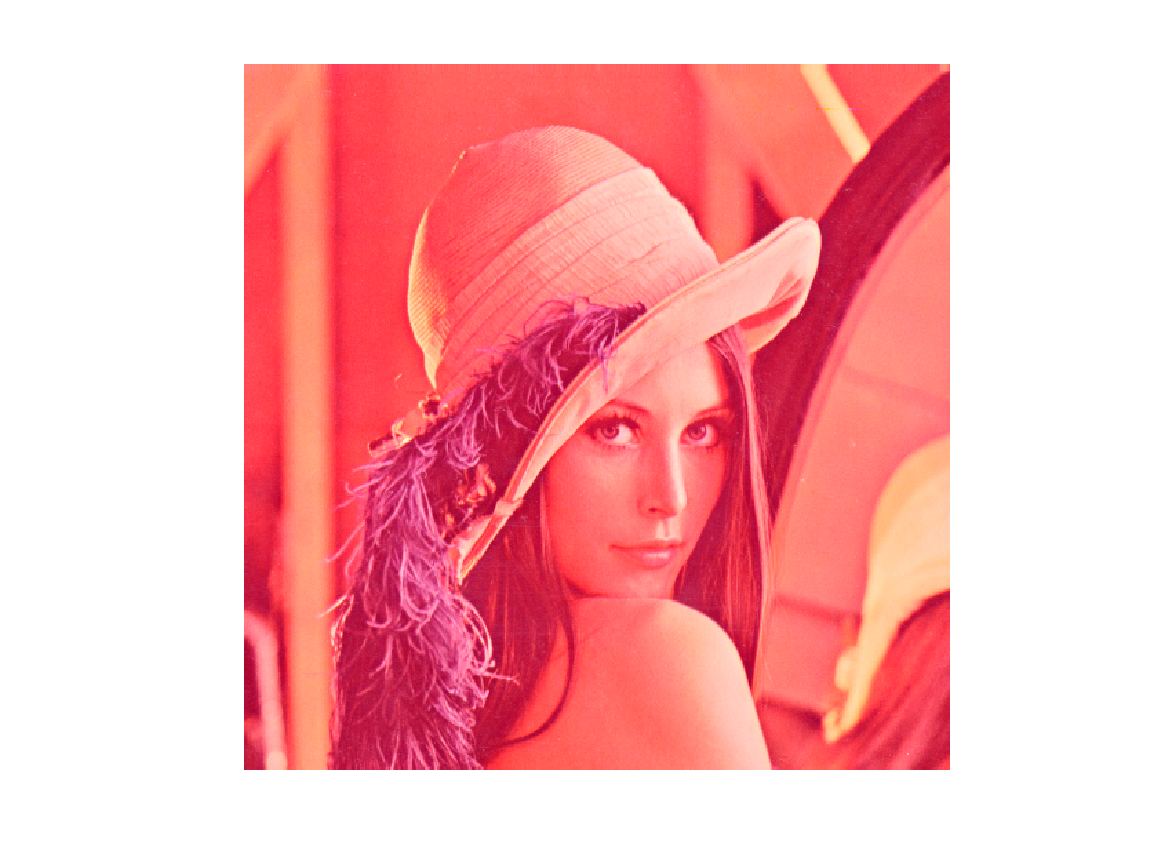

imshow(img_rgb_r)

disp('Display g-channel reinforced image')

Display g-channel reinforced image


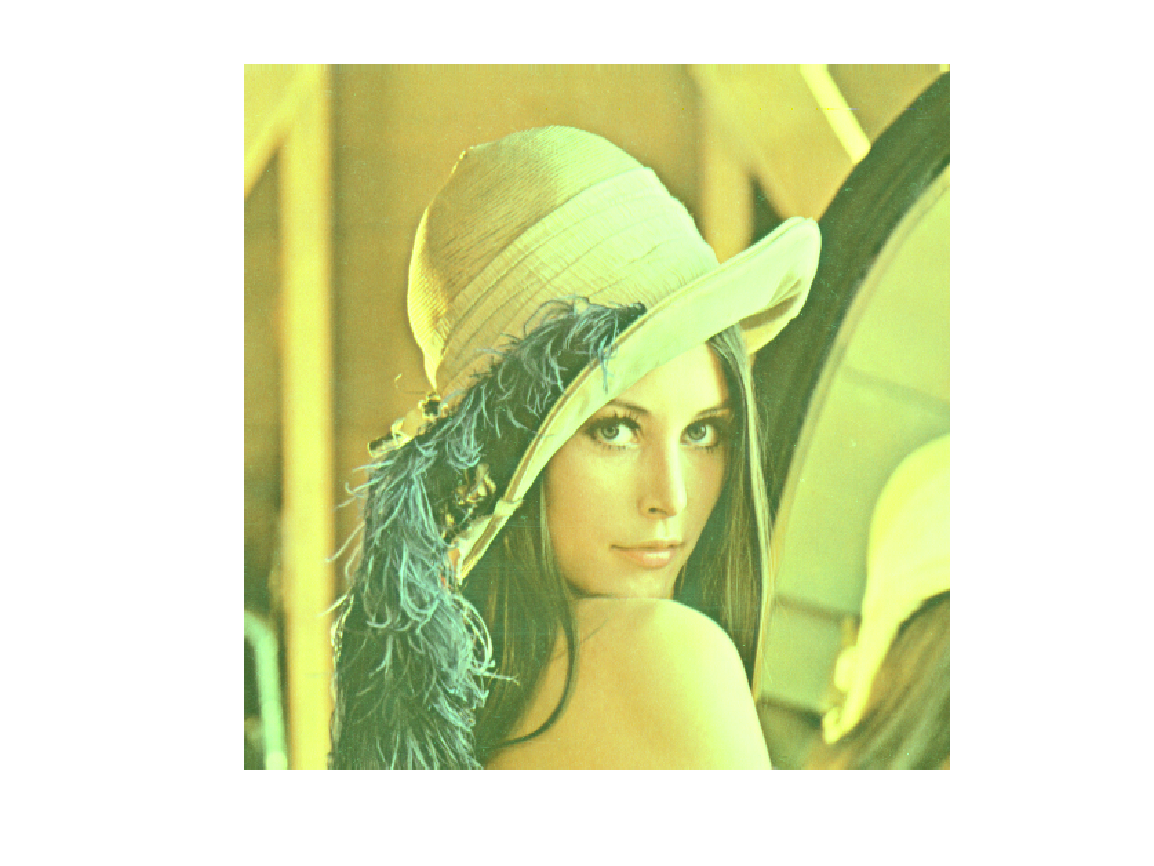

imshow(img_rgb_g)

disp('Display b-channel reinforced image')

Display b-channel reinforced image


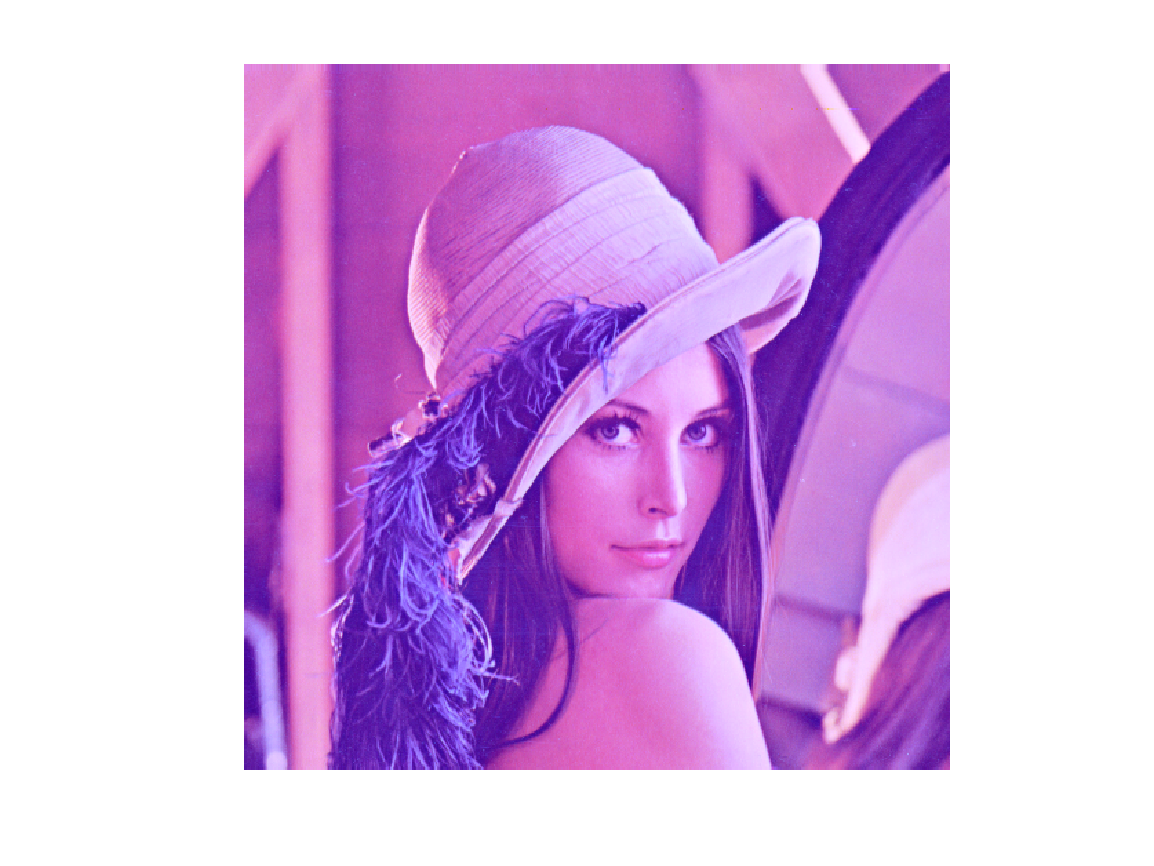

imshow(img_rgb_b)

## Elementwise operations on RGB image matrices

img_rgb_1 = img_rgb;
img_rgb_1(1:256, 1:256, 1) = 255; % Quadrant 2, R channel
img_rgb_1(1:256, 256:end, 2) = 255; % Quadrant 1, G channel
img_rgb_1(256:end, 256:end, 3) = 255; % Quadrant 4, B channel
disp('Display element-wise edited image')

Display element-wise edited image


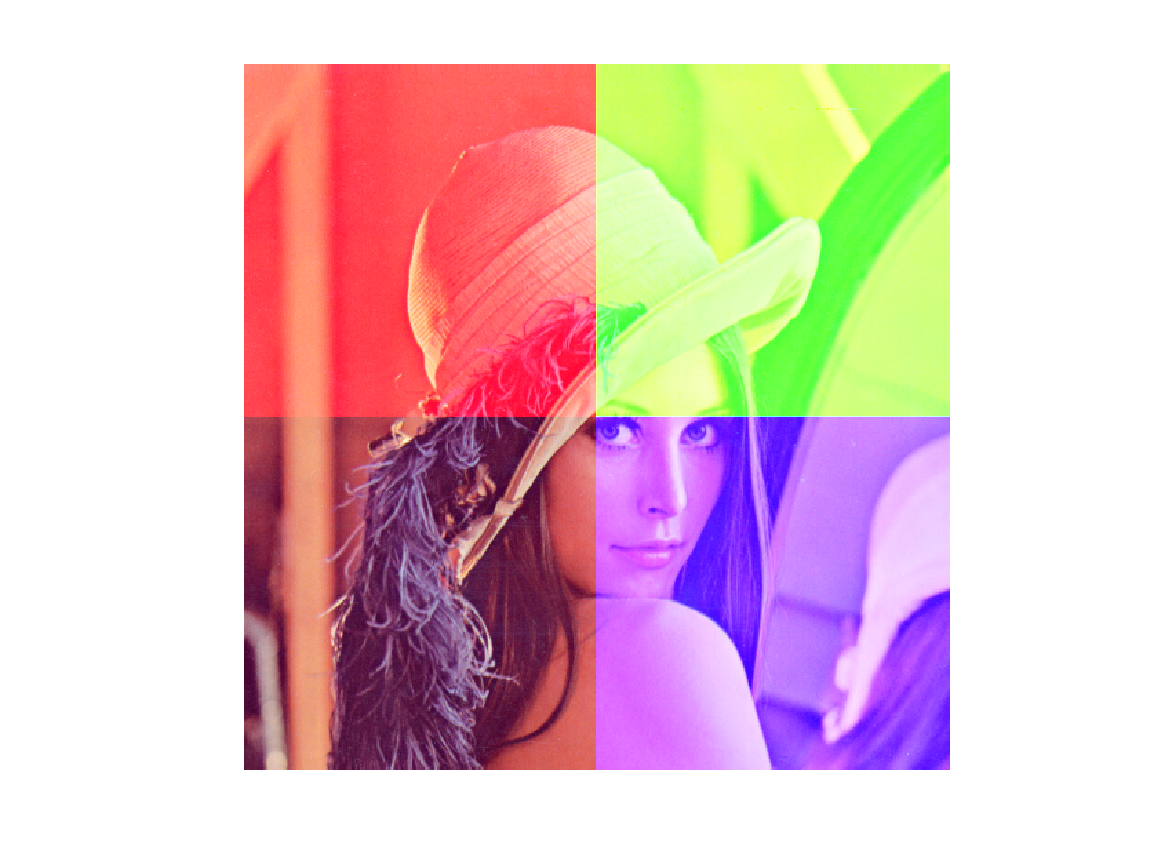

imshow(img_rgb_1)

## Color space conversion (RGB, HSV)

img_hsv = rgb2hsv(img_rgb);
disp('Display hsv transformed image')

Display hsv transformed image


imshow(img_hsv)

h = img_hsv(:, :, 1);
s = img_hsv(:, :, 2);
v = img_hsv(:, :, 3);
disp('Display h-channel grayscale image')

Display h-channel grayscale image


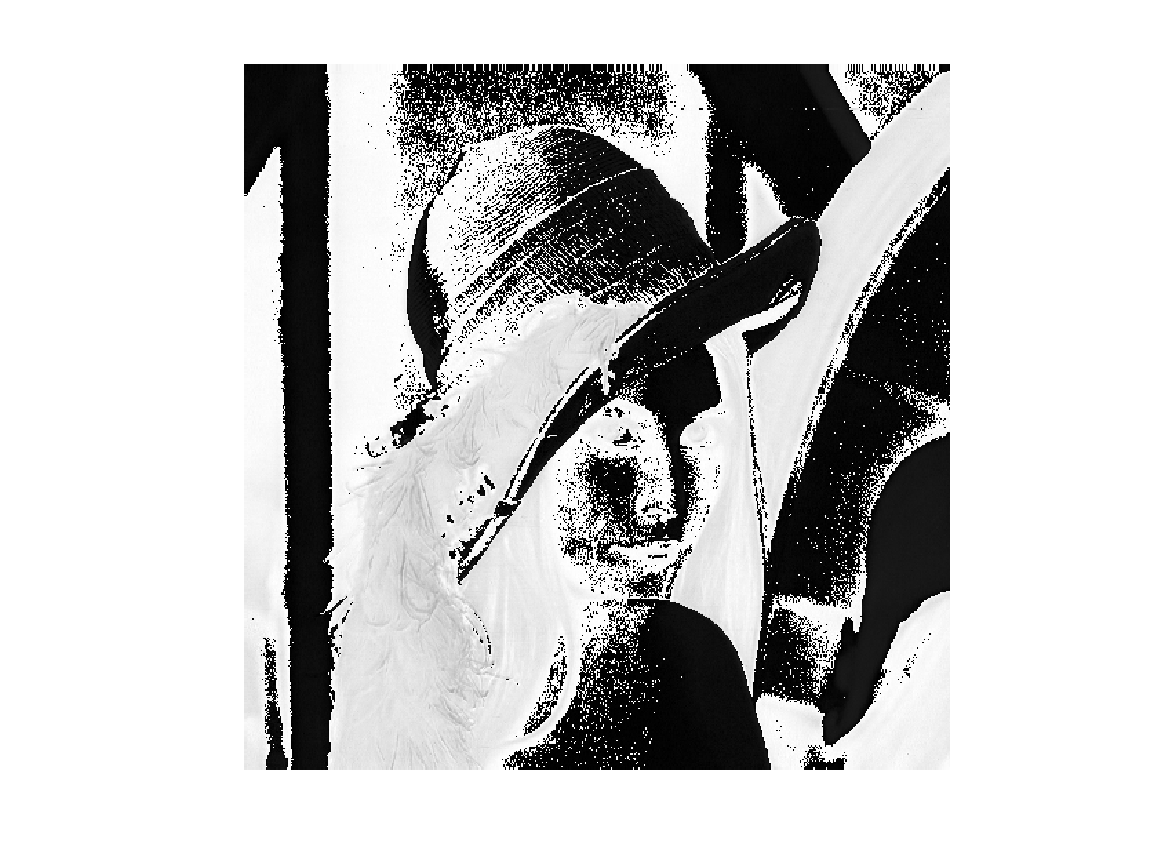

imshow(h)

disp('Display s-channel grayscale image')

Display s-channel grayscale image


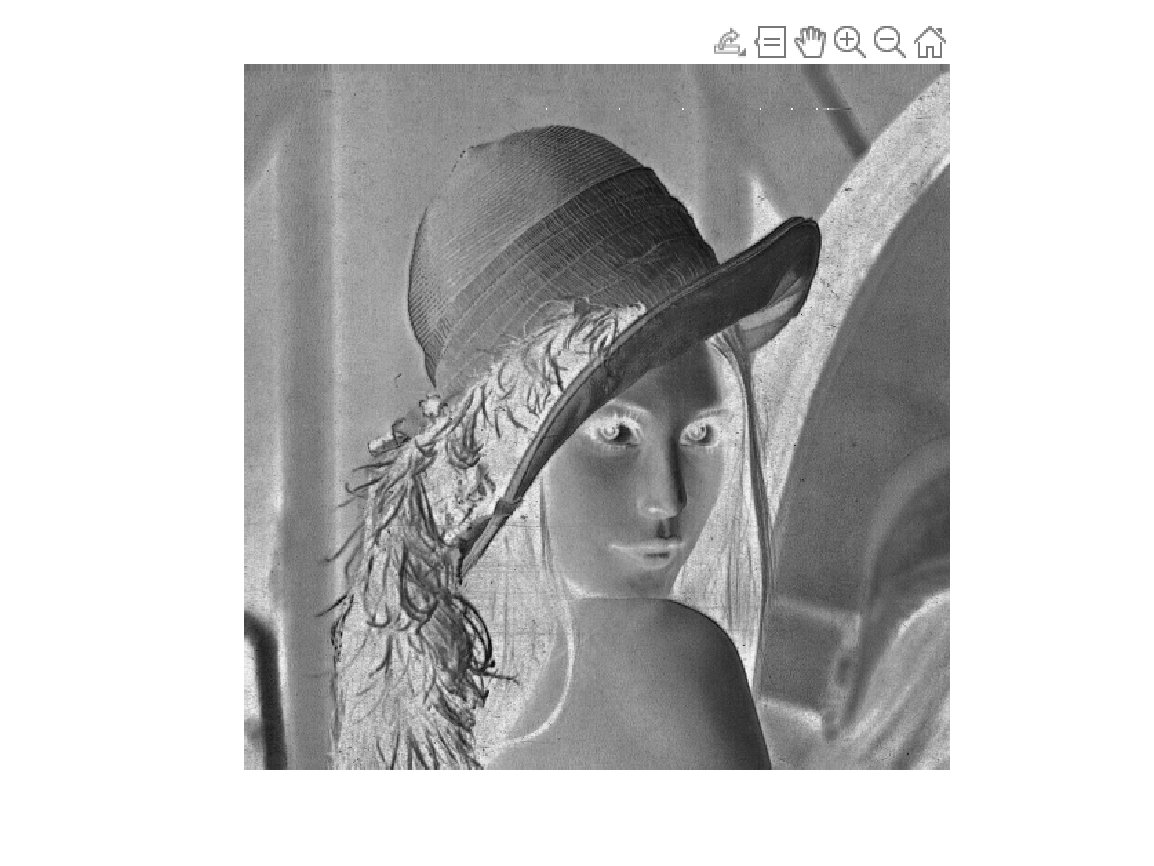

imshow(s)

disp('Display v-channel grayscale image')

Display v-channel grayscale image


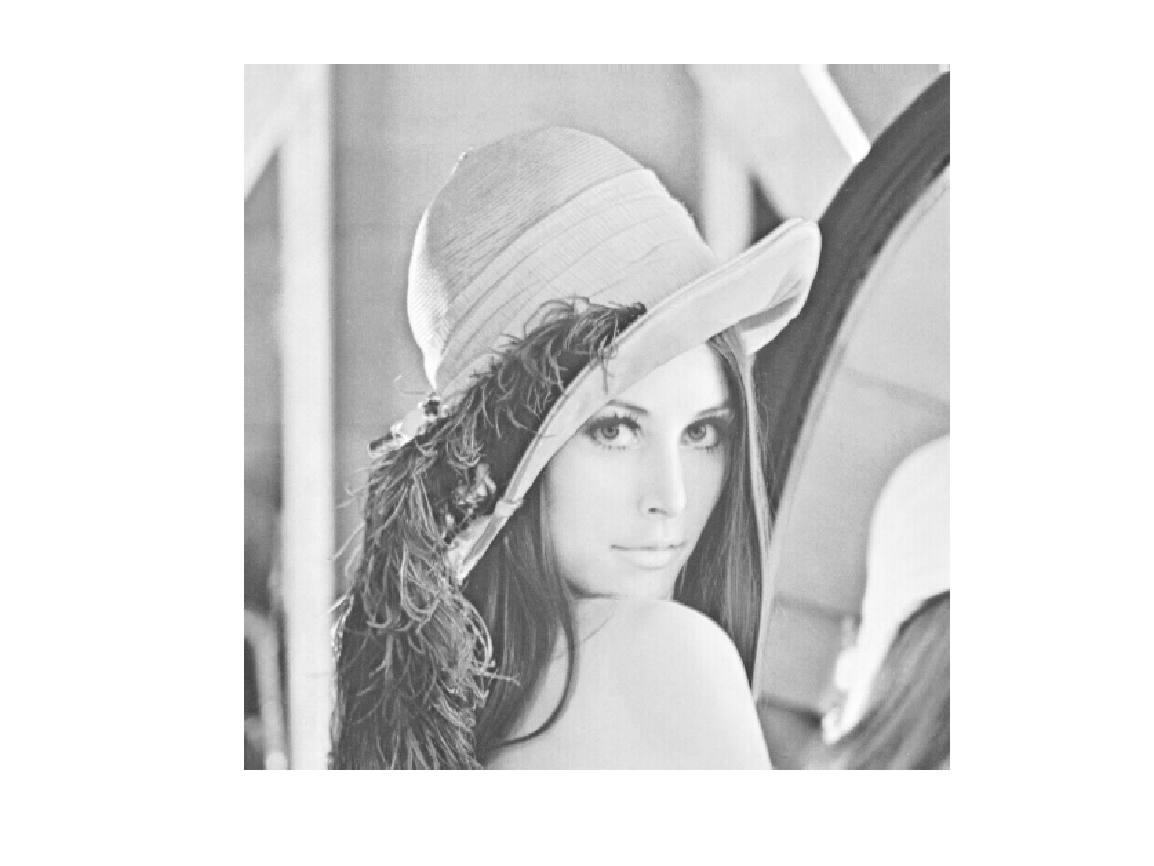

imshow(v)

## Extract a specific color region in HSV space

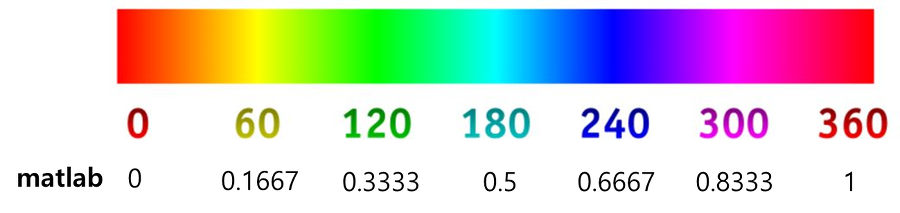

img_h_cut_hsv = img_hsv.*(h>0.67).*(h<0.83); % purple
img_h_cut_rgb = hsv2rgb(img_h_cut_hsv);
disp('Display purple area of the image')

Display purple area of the image


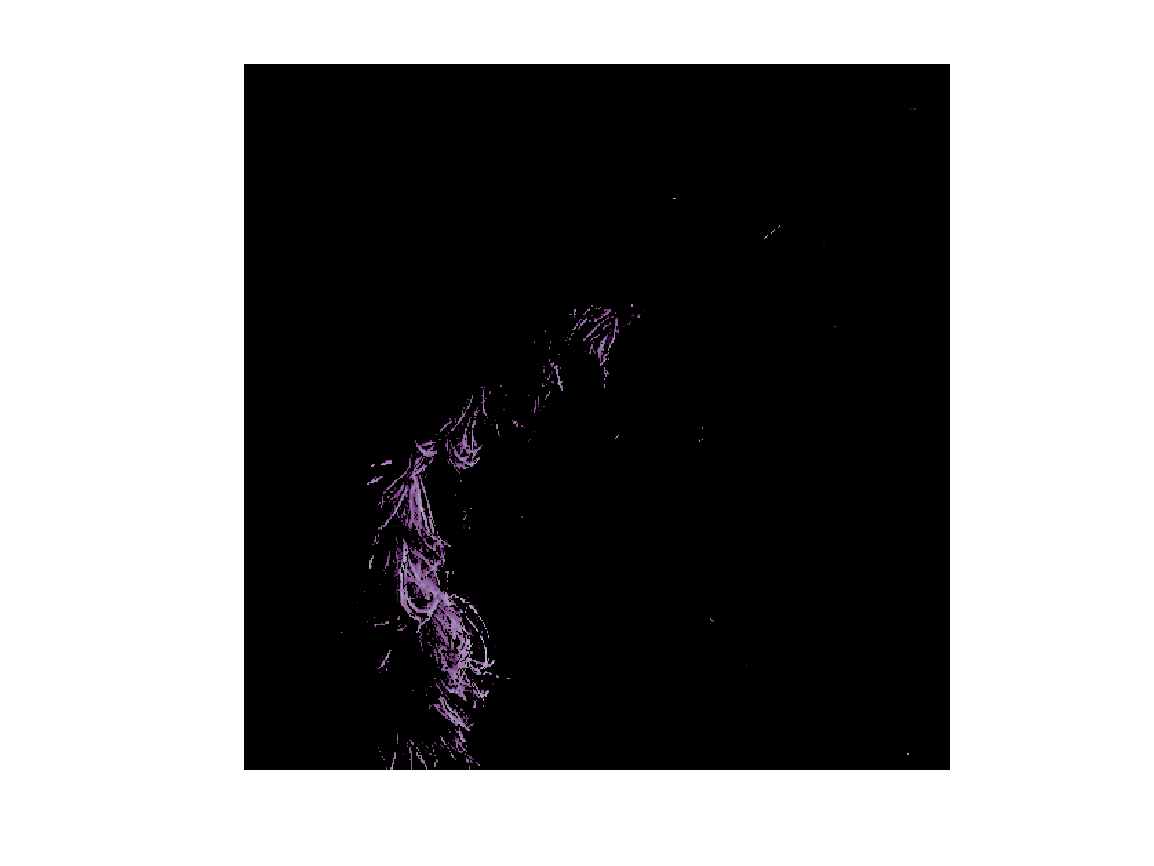

imshow(img_h_cut_rgb)

## Transform images

img_zoom_out = imresize(img_rgb, 0.5);
disp('Display 50% zoom out image');

Display 50% zoom out image


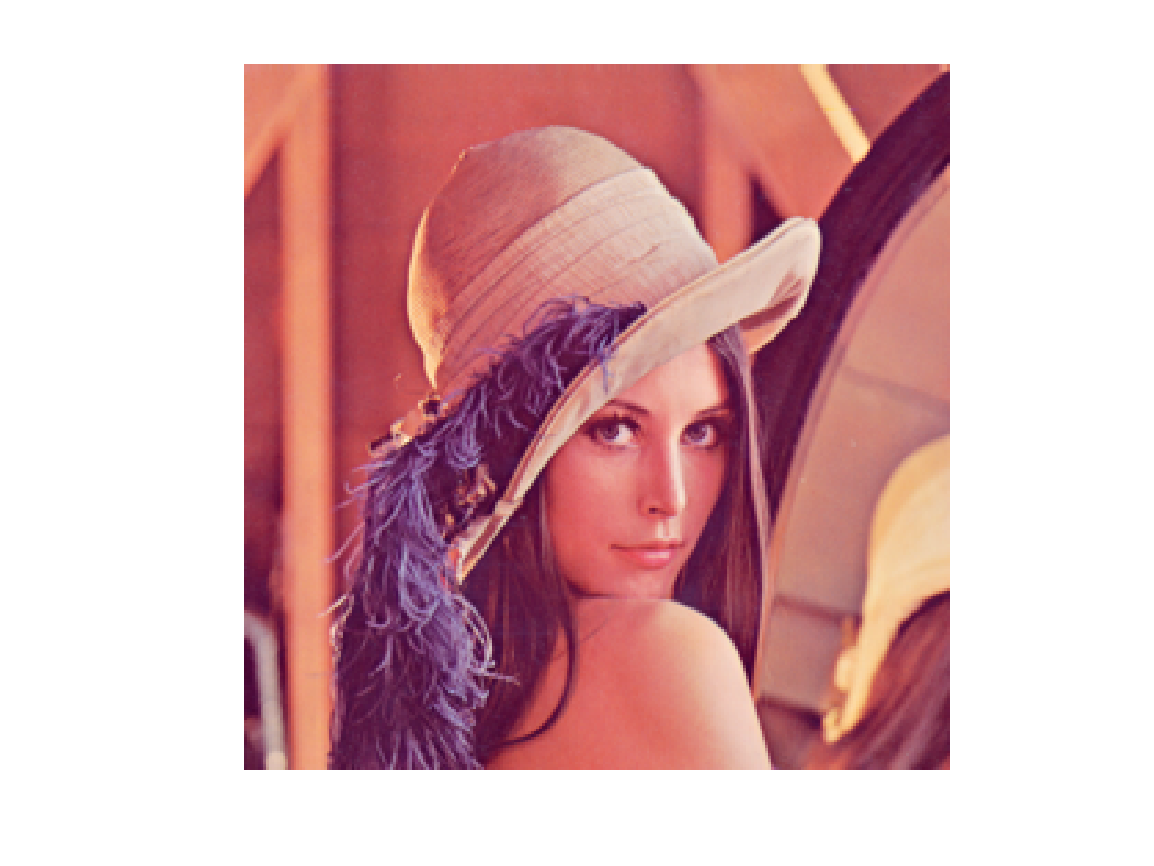

imshow(img_zoom_out)

img_trans = imresize(img_rgb, [100 50]);
disp('Display transformed image');

Display transformed image


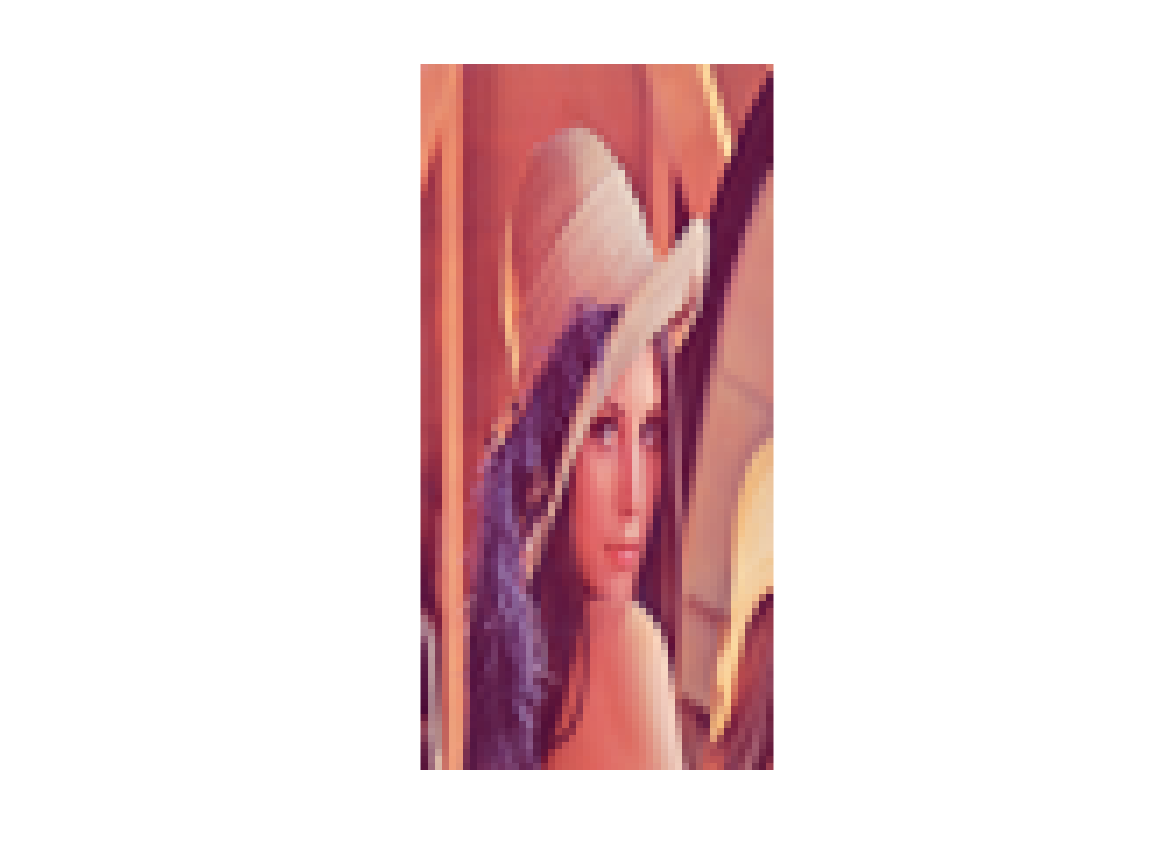

imshow(img_trans)

img_rotate1 = imrotate(img_rgb, 30);
disp('Display rotated image');

Display rotated image


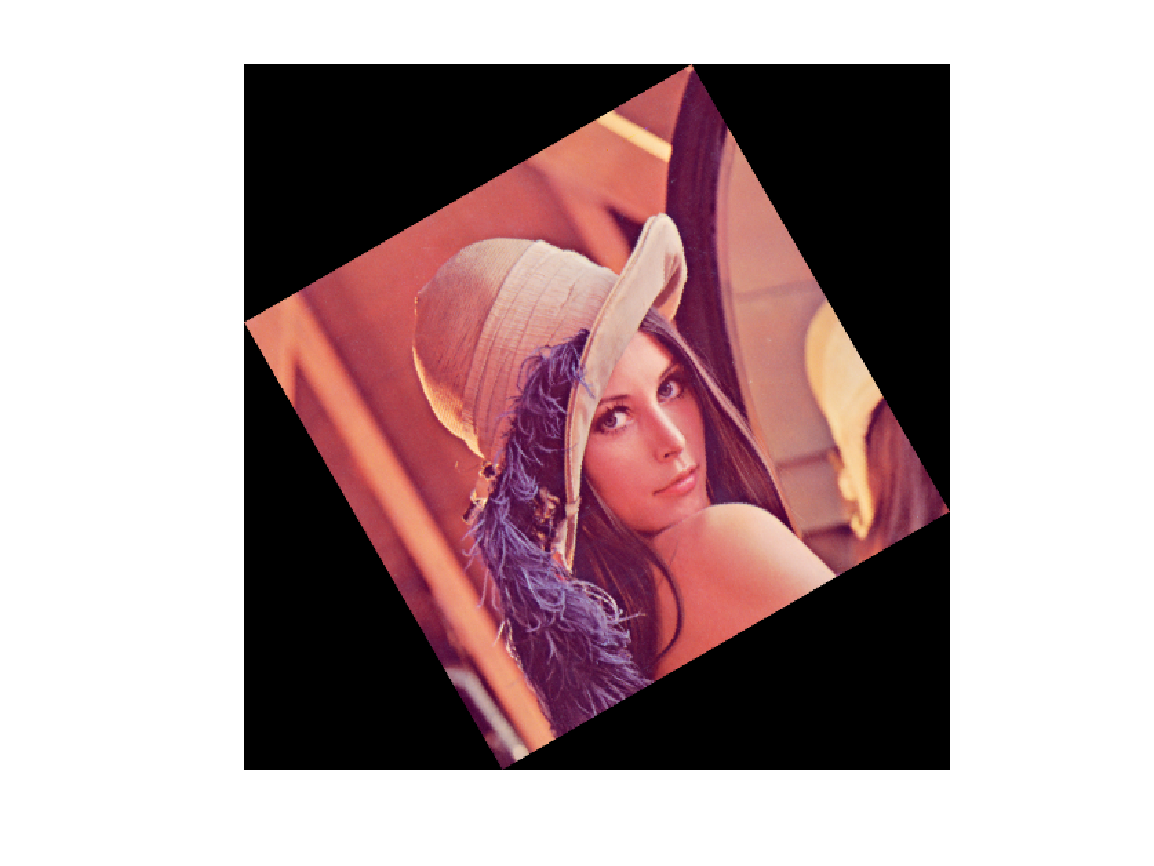

imshow(img_rotate1)

img_rotate2 = imrotate(img_rgb, 30, 'crop');
disp('Display rotated and cropped image');

Display rotated and cropped image


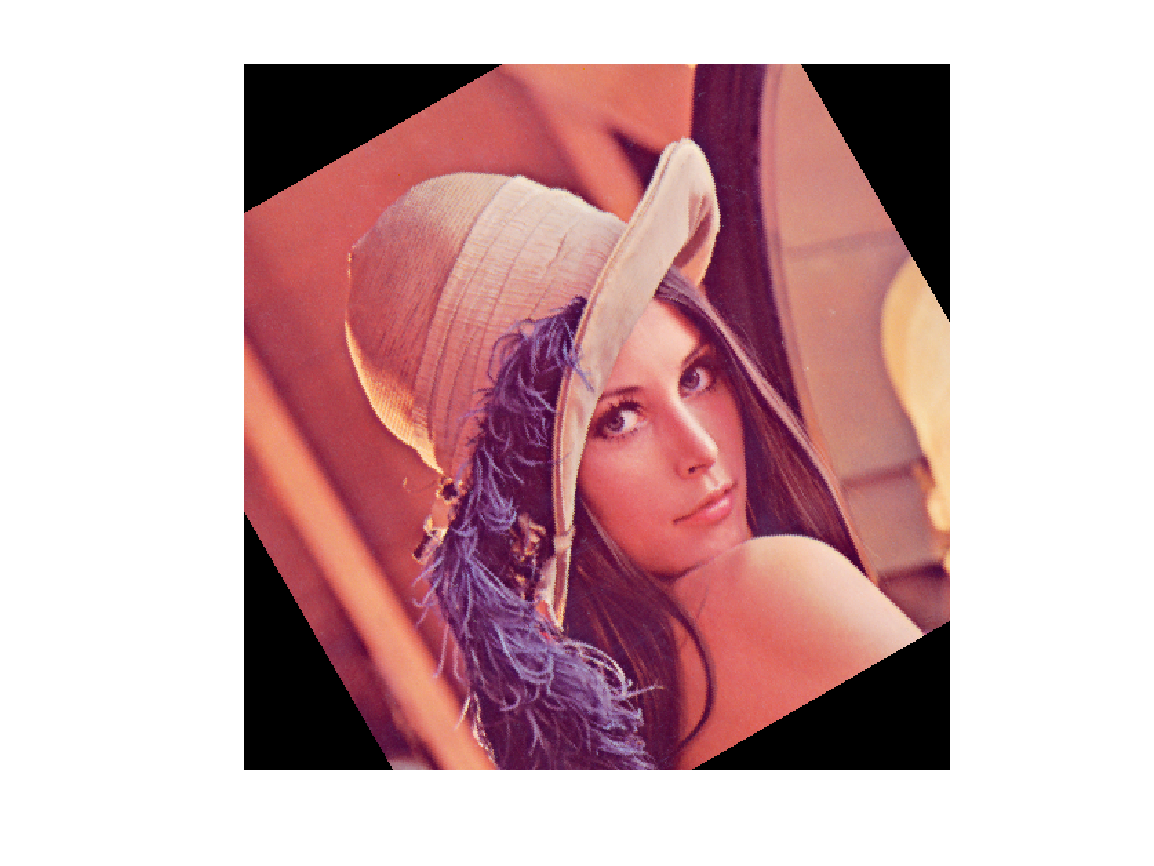

imshow(img_rotate2)

img_flip1 = flip(img_rgb, 1);
img_flip2 = flip(img_rgb, 2);
disp('Display vertically flipped image')

Display vertically flipped image


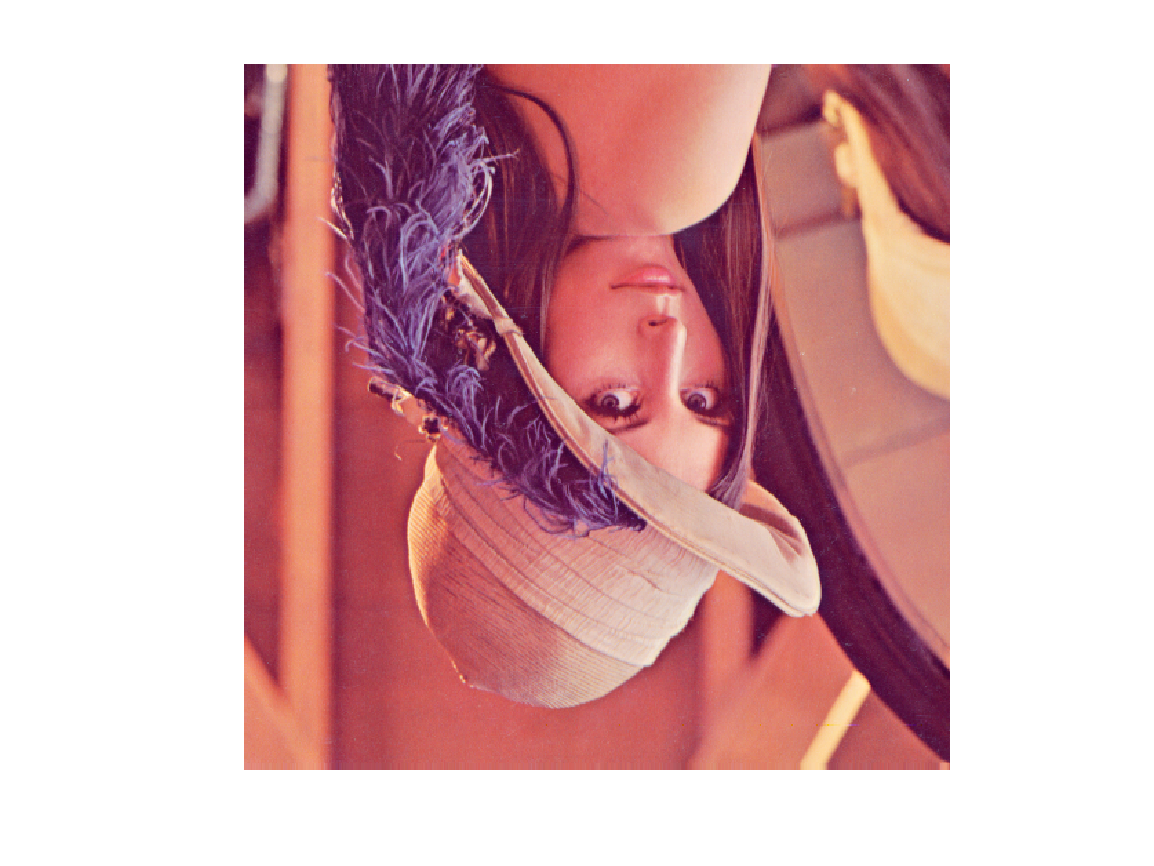

imshow(img_flip1)

disp('Display horizontally flipped image')

Display horizontally flipped image


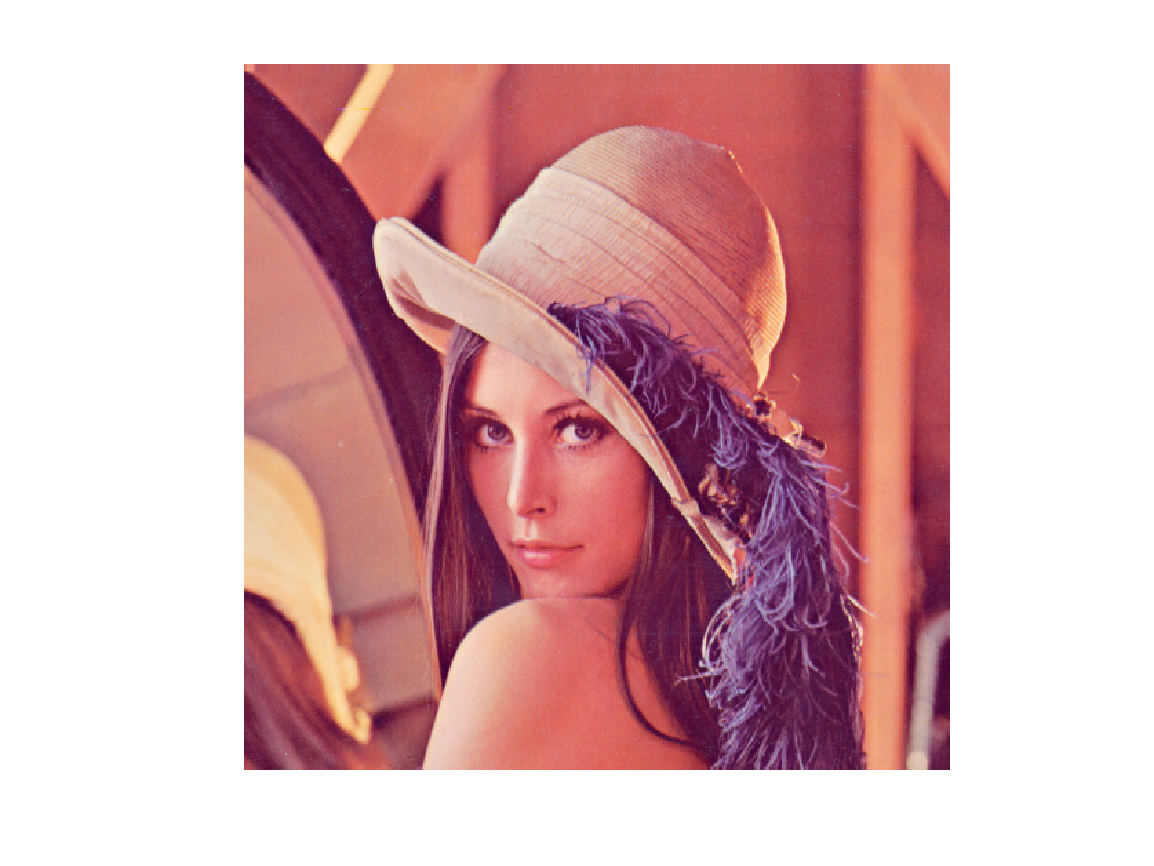

imshow(img_flip2)